clear; clear all; clc;
% parameters we want to change 
tlt = 20 % tilt we want
dw = 7 % amount of diverging waves we want
dwn = 4 % diverging wave number
% D2R = 30 %the degree width we want
fov = 120 % degree of field of view

for D2R = 10:10:120
    %% code from website with parameters put in 
    param = getparam('P4-2v');
    param.TXapodization = cos(linspace(-1,1,64)*pi/2);
    tilt = deg2rad(linspace(-1*tlt,tlt,dw)); % tilt angles in rad
    txdel = cell(dw,1); % this cell will contain the transmit delays
    
    for k = 1:dw
        txdel{k} = txdelay(param,tilt(k),deg2rad(D2R));
    end
        % stem(txdel{1}*1e6)
        % xlabel('Element number')
        % ylabel('Delays (\mus)')
        % title('TX delays for a 60{\circ}-wide -20{\circ}-tilted wave')
        % axis tight square
    
    
    [xi,zi] = impolgrid([100 100],15e-2,deg2rad(fov),param);
    option.WaitBar = false;
    P = pfield(xi,0*xi,zi,txdel{dwn},param,option);
    pcolor(xi*1e2,zi*1e2,20*log10(P/max(P(:))))
    shading interp
    xlabel('x (cm)')
    ylabel('z (cm)')
    title(['RMS pressure field for a ' num2str(D2R) '{\circ}' ...
        '-wide ' num2str(tlt) '{\circ}-tilted wave'])
    axis equal ij tight
    caxis([-20 0]) % dynamic range = [-20,0] dB
    cb = colorbar;
    cb.YTickLabel{end} = '0 dB';
    colormap(hot)
    
    %% All about the OG heart image 
    
        I = rgb2gray(imread('heart.jpg'));
        % Pseudorandom distribution of scatterers (depth is 15 cm)
        [x,y,z,RC] = genscat([NaN 15e-2],1540/param.fc,I);
        
        scatter(x*1e2,z*1e2,2,abs(RC).^.25,'filled')
        colormap([1-hot;hot])
        axis equal ij tight
        set(gca,'XColor','none','box','off')
        title('Scatterers for a cardiac 5-chamber view')
        ylabel('[cm]')
        
        RF = cell(7,1); % this cell will contain the RF series
        param.fs = 4*param.fc; % sampling frequency in Hz
        
        option.WaitBar = false; % remove the wait bar of SIMUS
        h = waitbar(0,'');
        for k = 1:7
            waitbar(k/7,h,['SIMUS: RF series #' int2str(k) ' of 7'])
            RF{k} = simus(x,y,z,RC,txdel{k},param,option);
        end
        close(h)
    
    %%  
    
    
    rf = RF{1}(:,32);
    t = (0:numel(rf)-1)/param.fs*1e6; % time (ms)
        % plot(t,rf)
        % set(gca,'YColor','none','box','off')
        % xlabel('time (\mus)')
        % title('RF signal of the 32^{th} element (1^{st} series, tilt = -20{\circ})')
        % axis tight
    
    %% Demodulate the RF signals with RF2IQ
    IQ = cell(7,1);  % this cell will contain the I/Q series
    
    for k = 1:7
        IQ{k} = rf2iq(RF{k},param.fs,param.fc);
    end
    
    iq = IQ{1}(:,32);
    %     plot(t,real(iq),t,imag(iq))
    %     set(gca,'YColor','none','box','off')
    %     xlabel('time (\mus)')
    %     title('I/Q signal of the 32^{th} element (1^{st} series, tilt = -20{\circ})')
    %     legend({'in-phase','quadrature'})
    %     axis tight
    
    [xi,zi] = impolgrid([256 128],15e-2,deg2rad(80),param);
    bIQ = zeros(256,128,7);  % this array will contain the 7 I/Q images
    
    h = waitbar(0,'');
    for k = 1:dw
        waitbar(k/7,h,['DAS: I/Q series #' int2str(k) ' of ' num2str(dw) ])
        bIQ(:,:,k) = das(IQ{k},xi,zi,txdel{k},param);
    end
    close(h)
    
    bIQ = tgc(bIQ); % time gain compensation 
    
    I = bmode(bIQ(:,:,dwn),50); % log-compressed image
        pcolor(xi*1e2,zi*1e2,I)
        shading interp, colormap gray
        title(['RMS pressure field for a ' num2str(D2R) '{\circ}' ...
                '-wide 0{\circ}-tilted wave'])
    
        axis equal ij
        set(gca,'XColor','none','box','off')
        c = colorbar;
        c.YTick = [0 255];
        c.YTickLabel = {'-50 dB','0 dB'};
        ylabel('[cm]')
    saveas(gcf,['Degree Wide' num2str(D2R) '.jpg'])
end

# Changing Width Degree

clear; clear all; clc;
% parameters we want to change 
tlt = 20 % tilt we want

tlt = 20

dw = 7 % amount of diverging waves we want

dw = 7

dwn = 4 % diverging wave number

dwn = 4

% D2R = 30 %the degree width we want
fov = 120 % degree of field of view

fov = 120

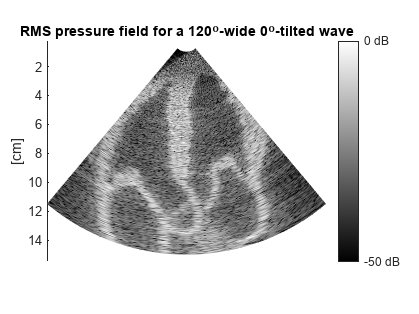


for D2R = 10:10:120
    %% code from website with parameters put in 
    param = getparam('P4-2v');
    param.TXapodization = cos(linspace(-1,1,64)*pi/2);
    tilt = deg2rad(linspace(-1*tlt,tlt,dw)); % tilt angles in rad
    txdel = cell(dw,1); % this cell will contain the transmit delays
    
    for k = 1:dw
        txdel{k} = txdelay(param,tilt(k),deg2rad(D2R));
    end
        % stem(txdel{1}*1e6)
        % xlabel('Element number')
        % ylabel('Delays (\mus)')
        % title('TX delays for a 60{\circ}-wide -20{\circ}-tilted wave')
        % axis tight square
    
    
    [xi,zi] = impolgrid([100 100],15e-2,deg2rad(fov),param);
    option.WaitBar = false;
    P = pfield(xi,0*xi,zi,txdel{dwn},param,option);
    pcolor(xi*1e2,zi*1e2,20*log10(P/max(P(:))))
    shading interp
    xlabel('x (cm)')
    ylabel('z (cm)')
    title(['RMS pressure field for a ' num2str(D2R) '{\circ}' ...
        '-wide ' num2str(tlt) '{\circ}-tilted wave'])
    axis equal ij tight
    caxis([-20 0]) % dynamic range = [-20,0] dB
    cb = colorbar;
    cb.YTickLabel{end} = '0 dB';
    colormap(hot)
    
    %% All about the OG heart image 
    
        I = rgb2gray(imread('heart.jpg'));
        % Pseudorandom distribution of scatterers (depth is 15 cm)
        [x,y,z,RC] = genscat([NaN 15e-2],1540/param.fc,I);
        
        scatter(x*1e2,z*1e2,2,abs(RC).^.25,'filled')
        colormap([1-hot;hot])
        axis equal ij tight
        set(gca,'XColor','none','box','off')
        title('Scatterers for a cardiac 5-chamber view')
        ylabel('[cm]')
        
        RF = cell(7,1); % this cell will contain the RF series
        param.fs = 4*param.fc; % sampling frequency in Hz
        
        option.WaitBar = false; % remove the wait bar of SIMUS
        h = waitbar(0,'');
        for k = 1:7
            waitbar(k/7,h,['SIMUS: RF series #' int2str(k) ' of 7'])
            RF{k} = simus(x,y,z,RC,txdel{k},param,option);
        end
        close(h)
    
    %%  
    
    
    rf = RF{1}(:,32);
    t = (0:numel(rf)-1)/param.fs*1e6; % time (ms)
        % plot(t,rf)
        % set(gca,'YColor','none','box','off')
        % xlabel('time (\mus)')
        % title('RF signal of the 32^{th} element (1^{st} series, tilt = -20{\circ})')
        % axis tight
    
    %% Demodulate the RF signals with RF2IQ
    IQ = cell(7,1);  % this cell will contain the I/Q series
    
    for k = 1:7
        IQ{k} = rf2iq(RF{k},param.fs,param.fc);
    end
    
    iq = IQ{1}(:,32);
    %     plot(t,real(iq),t,imag(iq))
    %     set(gca,'YColor','none','box','off')
    %     xlabel('time (\mus)')
    %     title('I/Q signal of the 32^{th} element (1^{st} series, tilt = -20{\circ})')
    %     legend({'in-phase','quadrature'})
    %     axis tight
    
    [xi,zi] = impolgrid([256 128],15e-2,deg2rad(80),param);
    bIQ = zeros(256,128,7);  % this array will contain the 7 I/Q images
    
    h = waitbar(0,'');
    for k = 1:dw
        waitbar(k/7,h,['DAS: I/Q series #' int2str(k) ' of ' num2str(dw) ])
        bIQ(:,:,k) = das(IQ{k},xi,zi,txdel{k},param);
    end
    close(h)
    
    bIQ = tgc(bIQ); % time gain compensation 
    
    I = bmode(bIQ(:,:,dwn),50); % log-compressed image
        pcolor(xi*1e2,zi*1e2,I)
        shading interp, colormap gray
        title(['RMS pressure field for a ' num2str(D2R) '{\circ}' ...
                '-wide 0{\circ}-tilted wave'])
    
        axis equal ij
        set(gca,'XColor','none','box','off')
        c = colorbar;
        c.YTick = [0 255];
        c.YTickLabel = {'-50 dB','0 dB'};
        ylabel('[cm]')
    saveas(gcf,['Degree Wide' num2str(D2R) '.jpg'])
end